clf;
clear;

house = imread("../images/house.tif");
[M,N] = size(house)

M = 512

N = 512

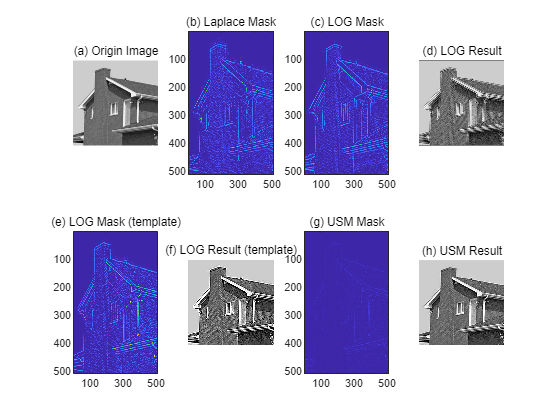

% imshow(house);

LOG = [0 0 -1 0 0; 0 -1 -2 -1 0; -1 -2 16 -2 -1; 0 -1 -2 -1 0; 0 0 -1 0 0];
Laplace = [1 1 1; 1 -8 1; 1 1 1];
k_USM = 10;

house_double = double(house);

G = Gaussian([3 3],1);
house_G = my_corr_same(house_double,G);
house_laplace = my_corr_same(house_G,Laplace);
Laplace_mask = my_corr_same(house,Laplace);
LOG_mask = my_corr_same(house_double,LOG);

house_LOG = 3*house_laplace + house_double;
house_LOG = uint8(house_LOG);
house_LOG_t = LOG_mask + house_double;
house_LOG_t = uint8(house_LOG_t);

USM_mask = house_double - house_G;
house_USM = k_USM*USM_mask + house_double;
house_USM = uint8(house_USM);

subplot(2,4,1);
imshow(house);title('(a) Origin Image');
subplot(2,4,2);
imagesc(uint8(Laplace_mask));title('(b) Laplace Mask');
subplot(2,4,3);
imagesc(uint8(house_laplace));title('(c) LOG Mask');
subplot(2,4,4);
imshow(house_LOG);title('(d) LOG Result');
subplot(2,4,5);
imagesc(uint8(LOG_mask));title('(e) LOG Mask (template)');
subplot(2,4,6);
imshow(house_LOG_t);title('(f) LOG Result (template)');
subplot(2,4,7);
imagesc(uint8(USM_mask));title('(g) USM Mask');
subplot(2,4,8);
imshow(house_USM);title('(h) USM Result');

function output = Gaussian(hsize, sigma)
hhsize = (hsize-1)/2;
[x,y] = meshgrid(-hhsize(2):hhsize(2),-hhsize(1):hhsize(1));
output = exp(-(x.*x + y.*y)/(2*sigma*sigma));

cum = sum(output(:));
output = output/cum;
end

%=========================
% corr_same
function result = my_corr_same(img, kernal)
[M,N] = size(img);
[k,kk] = size(kernal);
img_tmp = zeros(M+k-1,N+k-1);
result = zeros(M,N);

img_tmp(1+(k-1)/2:M+(k-1)/2,1+(k-1)/2:N+(k-1)/2) = img;

for i = 1:M
    for j = 1:N
        tmp = kernal.*img_tmp(i:i+k-1,j:j+kk-1);
        tmp = sum(tmp(:));
        result(i,j) = tmp;
    end
end
end